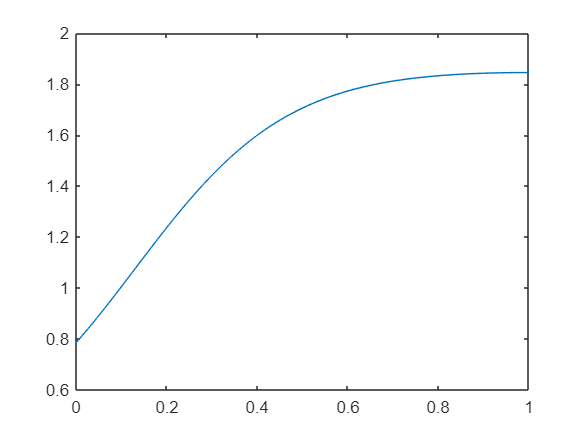

% equation 4 in force sat paper

alpha = 1;
mag_Gamma = linspace(0,1);
epsilon = -1;

sigma_1 = alpha.^2*mag_Gamma.^2 + 1;
sigma_2 = alpha*(mag_Gamma.^2 + 1);
sigma = sqrt( sigma_1.^2 + sigma_2.^2);

arg_tan = (alpha.^2*mag_Gamma.^2 + 1) ./ (sigma + epsilon*alpha*(1+mag_Gamma).^2);
ang_Gamma_opt = 2*atan(arg_tan) + epsilon * acos(-2*alpha*mag_Gamma./sigma);

figure
plot(mag_Gamma,wrapToPi(ang_Gamma_opt))

% seems to not work - either there is a typo above or eqn 4 is wrong

% using expression from electrical_impedance_match.mlx
sigma_1 = alpha^2 + 1;
sigma_2 = alpha^2 * mag_Gamma.^4 + 1;
sigma = sqrt(sigma_1 * sigma_2);

sigma =     1.4142    1.4142    1.4142    1.4142    1.4142    1.4142    1.4142    1.4142    1.4142    1.4143    1.4143    1.4143    1.4144    1.4144    1.4145    1.4146    1.4147    1.4148    1.4150    1.4152    1.4154    1.4156    1.4159    1.4163    1.4167    1.4171    1.4176    1.4181    1.4187    1.4194    1.4202    1.4210    1.4219    1.4229    1.4240    1.4252    1.4265    1.4279    1.4295    1.4311    1.4329    1.4349    1.4369    1.4392    1.4415    1.4441    1.4468    1.4497    1.4528    1.4560


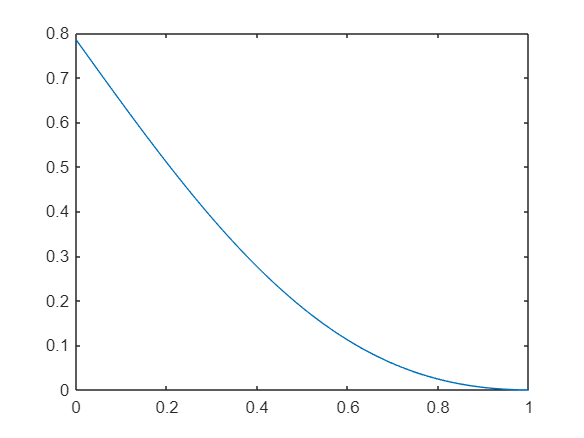

arg_tan = (alpha.^2*mag_Gamma.^2 + 1 - sigma) ./ (alpha * mag_Gamma.^2 + 2*alpha*mag_Gamma + alpha);
ang_Gamma_opt = -2 * atan(arg_tan);

figure
plot(mag_Gamma,wrapToPi(ang_Gamma_opt))